# べき分布に従う乱数の生成とべき指数の見積もり

べき分布に従う乱数の生成とべき指数の見積もり

clear all; clf;

## （次数）分布の生成

べき分布 $y=ax^b$ に従う $N$ 個の乱数を生成する．

$x$の上限値を $M$, 下限値を $m$ として、確率密度分布は $p(x)=\frac{b+1}{M^{b+1}-m^{b+1}}x^{b}$

対数的に等間隔か線形で等間隔によって、べき指数が異なることに注意

→**線形で等間隔の方が正しい**

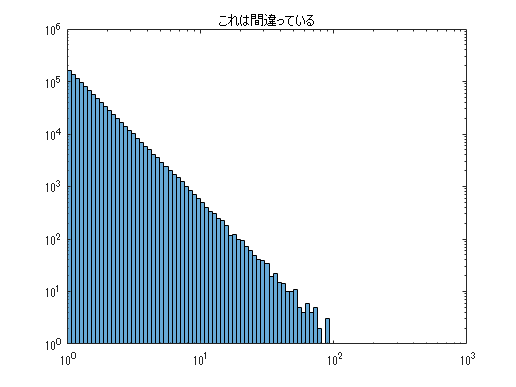

N = 1000000;
M = 1000;
m = 1;
b = -3.5; % b=1/(1-gamma) gamma=3
%べき指数はb

x = rand(1, N);
y = (x.*M^(1+b)+(1-x).*m^(1+b)).^(1/(1+b));
%y = fix(y); % 整数部分の取得
y = sort(y,'descend'); % 降順に並べ替え

%対数的に等間隔な場合、べき指数はb+1になる。
edges = logspace(0, 3, 100);
histogram(y, edges)
set(gca, 'Xscale', 'log');
set(gca, 'Yscale', 'log');
title("これは間違っている")


%線形で等間隔な場合、べき指数はb程度
h = histogram(y, 100);
x0 = h.BinEdges(1:end-1) %Bin の値はこの方が良さそう

x0 =          0    4.1700    8.3400   12.5100   16.6800   20.8500   25.0200   29.1900   33.3600   37.5300   41.7000   45.8700   50.0400   54.2100   58.3800   62.5500   66.7200   70.8900   75.0600   79.2300   83.4000   87.5700   91.7400   95.9100  100.0800  104.2500  108.4200  112.5900  116.7600  120.9300  125.1000  129.2700  133.4400  137.6100  141.7800  145.9500  150.1200  154.2900  158.4600  162.6300  166.8000  170.9700  175.1400  179.3100  183.4800  187.6500  191.8200  195.9900  200.1600  204.3300


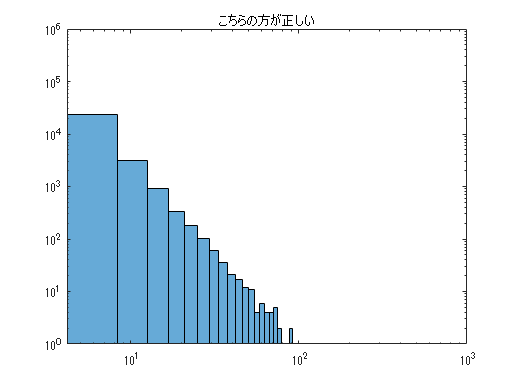

% x0 = movsum(h.BinEdges, 2)/2;
% x0 = x0(2:end);
y0 = h.Values;
set(gca, 'Xscale', 'log');
set(gca, 'Yscale', 'log');
title("こちらの方が正しい")

### 累積分布を求める

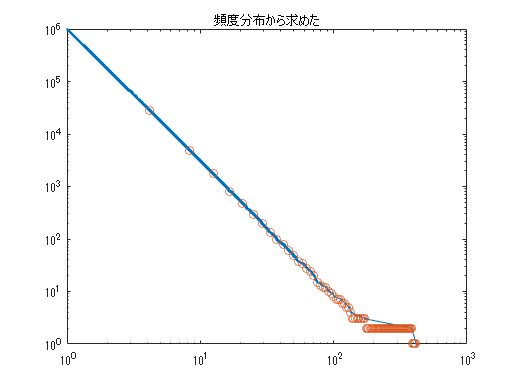

%ランキングプロット：相補累積
loglog(y, 1:1:N, '.-')
%title("ランキングプロット")
hold on
%頻度分布から求めた累積
loglog(x0, cumsum(y0,'reverse'), 'o')
title("頻度分布から求めた")
hold off

### べき指数の見積もり

以下の論文の式(3.7)による、確率密度分布のべき指数の計算。

    from

    Power-Law Distributions in Empirical Data

    Aaron Clauset, Cosma Rohilla Shalizi and M. E. J. Newman

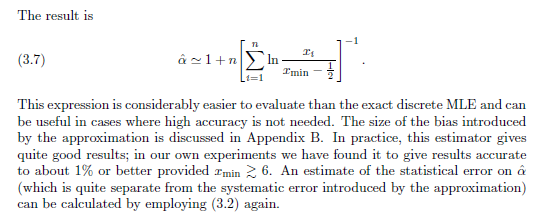

注：上記の、正確な結果が得られる条件 $x_{\mathrm{min}}\geq 6$ は重要である。

実際ここではべき分布に従う乱数は $y_i$ であり、その全データーに対して上式を適用すると、初めに与えたべき指数 $b$ と合わなかった。

そこで以下のように $y_i\ge 6$ となるデータのみを用いてべき指数を求めたところ、満足のいく結果が得られた。

y1 = y(1:500) % y >= 6 となるようなデータのみに着目している。

y =   416.3646  384.6548  173.6668  135.6488  130.9633  122.4996  114.9283  100.6031   98.6732   92.4134   89.7876   88.9403   82.0115   79.2273   75.7996   74.2892   72.6977   72.5110   72.3307   72.1830   69.4359   69.4046   68.4456   67.7683   65.6942   64.9635   63.7700   63.3922   62.3179   61.4313   61.2476   60.1032   59.3085   58.9589   56.3059   56.0931   54.2417   54.2403   53.5153   52.9989   52.8275   52.7861   52.7403   51.9592   51.6363   51.6192   50.3365   50.2131   50.0802   49.8380


y1 =   416.3646  384.6548  173.6668  135.6488  130.9633  122.4996  114.9283  100.6031   98.6732   92.4134   89.7876   88.9403   82.0115   79.2273   75.7996   74.2892   72.6977   72.5110   72.3307   72.1830   69.4359   69.4046   68.4456   67.7683   65.6942   64.9635   63.7700   63.3922   62.3179   61.4313   61.2476   60.1032   59.3085   58.9589   56.3059   56.0931   54.2417   54.2403   53.5153   52.9989   52.8275   52.7861   52.7403   51.9592   51.6363   51.6192   50.3365   50.2131   50.0802   49.8380


ymin = y1(500)

ymin = 20.5190

S = sum(log(y1/(ymin-0.5)))

S = 203.0179

gamma_hat = -(1 + 500/S)

gamma_hat = -3.4628

u = 1:1:N;